# Question 3

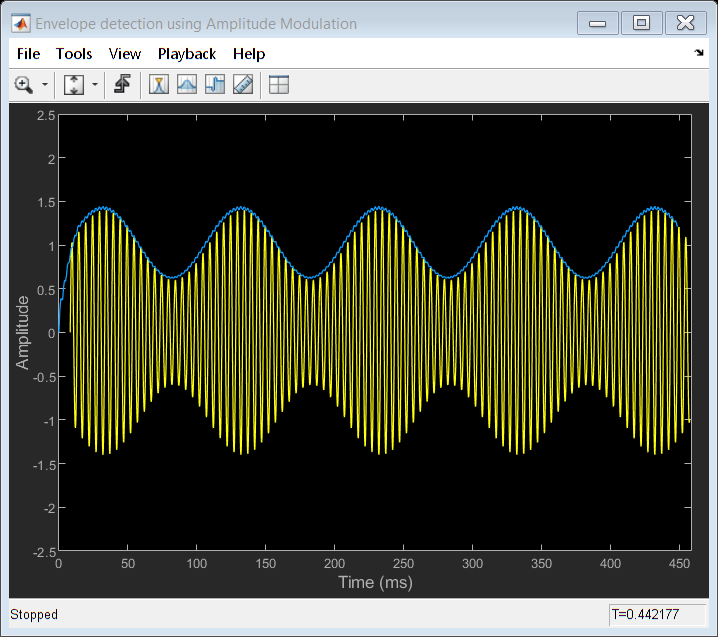

clc;
clear;
Fs = 22050;
numSamples = 10000;
DownsampleFactor = 15;
frameSize = 10*DownsampleFactor;
% first Domain 0.4,second Domain 1
% first Frequency 10,second Frequency 200
sine = dsp.SineWave([0.4 1],[10 200], ...
    'SamplesPerFrame',frameSize, ...
    'SampleRate',Fs);
% first Domain 0.4,second Domain 1
% first Frequency 10,second Frequency 200

% lowpass filter
lp1 = dsp.FIRFilter('Numerator',firpm(20,[0 0.03 0.1 1],[1 1 0 0]));
N = 60; % Filter order

%hilbert Transform
hilbertTransformer = dsp.FIRFilter( ...
        'Numerator',firpm(N,[0.01 .95],[1 1],'hilbert'));
% delay box    
delay = dsp.Delay('Length',N/2);

% another lowpass filter
lp2 = dsp.FIRFilter('Numerator',firpm(20,[0 0.03 0.1 1],[1 1 0 0]));

% scope 1 -> envelope detection usign AM modulation
scope1 = dsp.TimeScope( ...
  'NumInputPorts',2, ...
  'Name','Envelope detection using Amplitude Modulation', ...
  'SampleRate',[Fs,Fs/DownsampleFactor], ...
  'TimeDisplayOffset',[(N/2+frameSize)/Fs,0], ...
  'TimeSpanSource','Property', ...
  'TimeSpan',0.45, ...
  'YLimits',[-2.5 2.5], ...
  'TimeSpanOverrunAction','Scroll');
pos = scope1.Position;

% scope 2 -> envelope detection using Hilbert modulation
scope2 = dsp.TimeScope( ...
  'NumInputPorts',2, ...
  'Name','Envelope detection using Hilbert Transform', ...
  'Position',[pos(1)+pos(3),pos(2:4)], ...
  'SampleRate',[Fs,Fs/DownsampleFactor], ...
  'TimeDisplayOffset',[(N/2+frameSize)/Fs,0], ...
  'TimeSpanSource','Property', ...
  'TimeSpan',0.45, ...
  'YLimits',[-2.5 2.5], ...
  'TimeSpanOverrunAction','Scroll');
%%

% exmaple
for i = 1:numSamples/frameSize
    sig = sine();
    sig = (1 + sig(:,1)) .* sig(:, 2);      % Amplitude modulation

    % Envelope detector by squaring the signal and lowpass filtering
    sigsq = 2 * sig .* sig;
    sigenv1 = sqrt(lp1(downsample(sigsq,DownsampleFactor)));

    % Envelope detector using the Hilbert transform in the time domain
    sige = abs(complex(0, hilbertTransformer(sig)) + delay(sig));
    sigenv2 = lp2(downsample(sige,DownsampleFactor));

    % Plot the signals and envelopes
    scope1(sig,sigenv1);
    scope2(sig,sigenv2);
end
release(scope1);

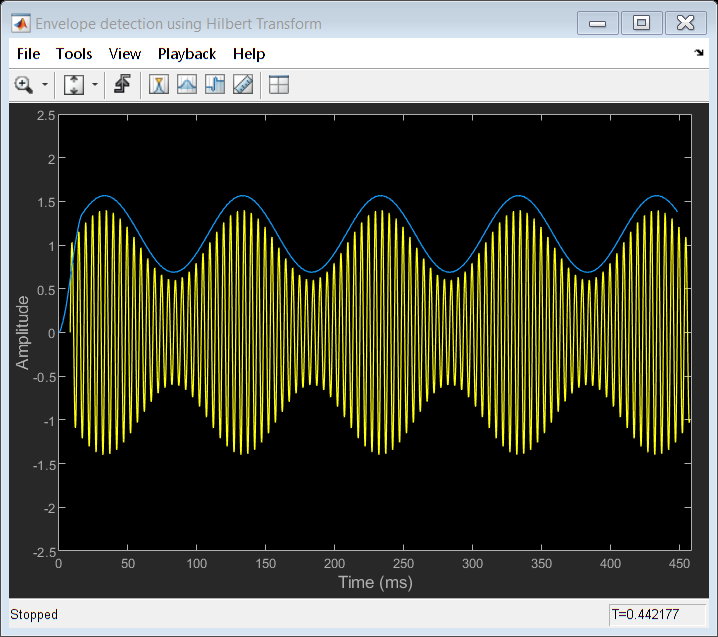

release(scope2);

## coherent demodulator

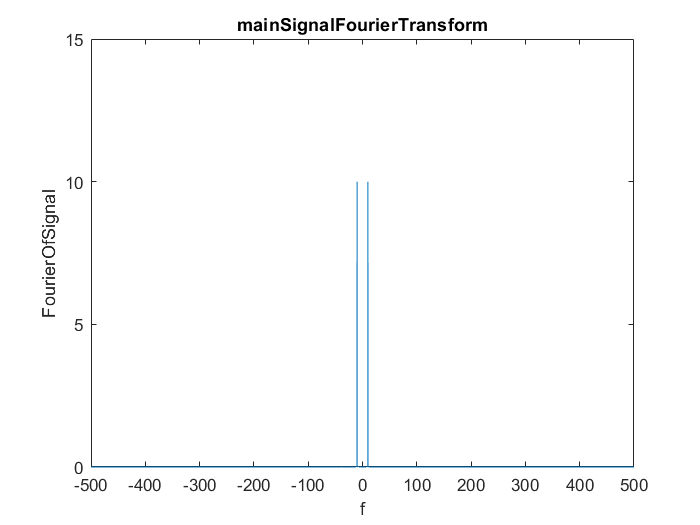

MainSignalFourierTransformAmplitude = 9.9991

Tsamping = 0.001; %1ms
fs = 1/Tsamping; % 1kHz
t = -10:Tsamping:10;

% main signal
fm = 10; 
signal = cos(2*pi*fm*t);
[signalFourier, freqDomain] = standardFourierTransform(signal,fs);
plot(freqDomain,abs(signalFourier))
title('mainSignalFourierTransform')
ylim([0 15])
xlabel('f')
ylabel('FourierOfSignal')
MainSignalFourierTransformAmplitude = max(abs(signalFourier))

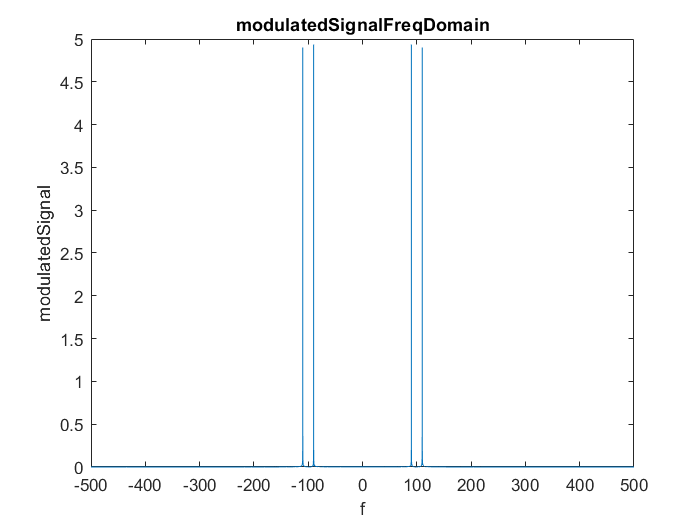

% cosinus signal via 1Hz frequecny and sampling Rate of 1k.

%%carrier
% we assume that Ac=1
fc = 100;
cari = cos(2*pi*fc*t); % same sampling Rates.
modulatedsignal= signal.*cari ;
[modfourier, modf] = standardFourierTransform(modulatedsignal,fs);
plot(modf,abs(modfourier))
title('modulatedSignalFreqDomain')
xlabel('f')
ylabel('modulatedSignal')


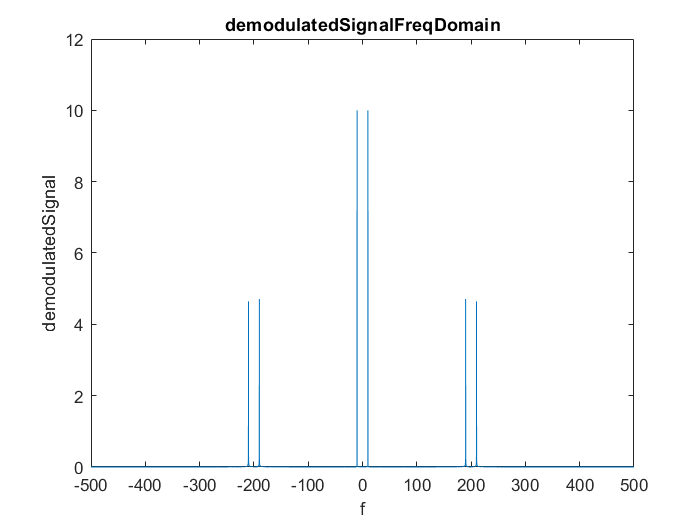

demodul = 2.*cari.*modulatedsignal;
[demfourier, demf] = standardFourierTransform(demodul,fs);
plot(demf,abs(demfourier))
title('demodulatedSignalFreqDomain')
xlabel('f')
ylabel('demodulatedSignal')
load('lowPassFilter.mat')

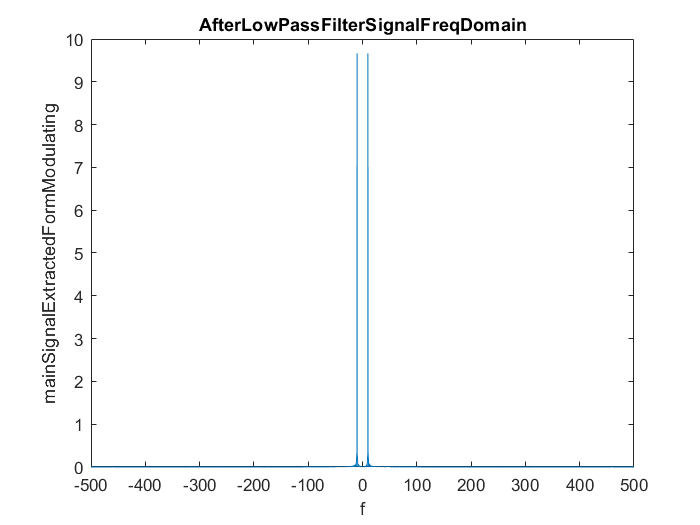

filtered_signal = filter(lowPassFilter,demodul);
[filterSignalTransform, filteredF] = standardFourierTransform(filtered_signal,fs);
plot(filteredF,abs(filterSignalTransform))
title('AfterLowPassFilterSignalFreqDomain')
xlabel('f')
ylabel('mainSignalExtractedFormModulating')
FreqAmpWithoutPhase = max(abs(filterSignalTransform))

%phase error part

FreqAmpWithoutPhase = 9.6635

%%carrier
% we assume that Ac=1
fc = 100;
rndphase = 2*pi*rand
cariViaPhase = cos(2*pi*fc*t + rndphase); % same sampling Rates.

rndphase = 6.0162

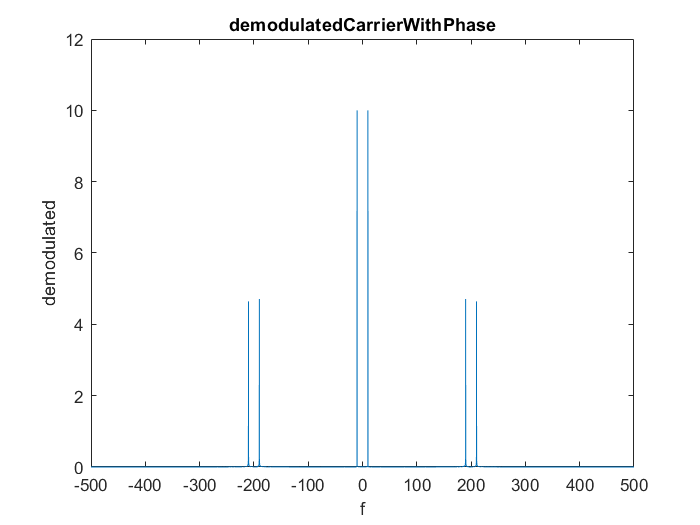

demodulPhase = 2.*modulatedsignal.*cariViaPhase;
[demfourier, demf] = standardFourierTransform(demodul,fs);
plot(demf,abs(demfourier))
title('demodulatedCarrierWithPhase')
xlabel('f')
ylabel('demodulated')


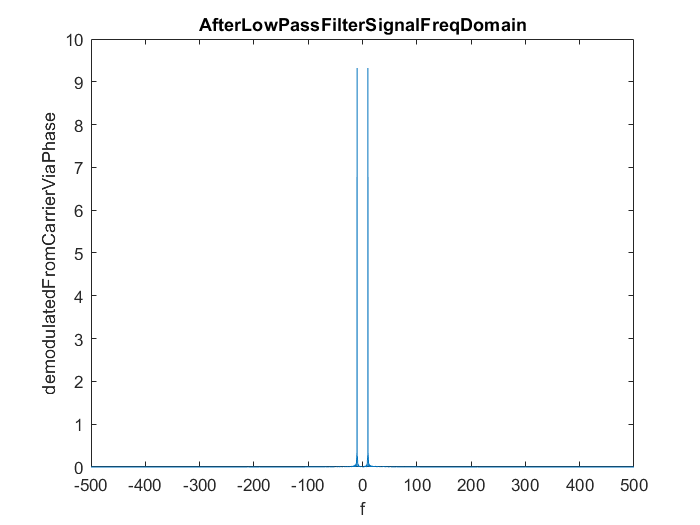

filtered_signalPhase = filter(lowPassFilter,demodulPhase);
[filterSignalTransform, filteredF] = standardFourierTransform(filtered_signalPhase,fs);
plot(filteredF,abs(filterSignalTransform))
title('AfterLowPassFilterSignalFreqDomain')
xlabel('f')
ylabel('demodulatedFromCarrierViaPhase')
FreqAmpViaPhase = max(abs(filterSignalTransform))

AmpDampRate = FreqAmpViaPhase/MainSignalFourierTransformAmplitude 

FreqAmpViaPhase = 9.3213

cos(rndphase)

AmpDampRate = 0.9322

ans = 0.9646

%edittion
errorViaPhase = immse(filtered_signalPhase./cos(rndphase),signal);
vpa(errorViaPhase)


function [out,standardDomain] = standardFourierTransform(signal,fs)
n = length(signal);
fourier=fft(signal,n);
fourier = fourier/fs;
out = fftshift(fourier);
domain = linspace(-pi,pi,length(out));
standardDomain = domain*fs/(2*pi);
end
